close all

setup

t0 = 10;
T = {[-17.45,-38.443],[-71.499,-102.36],[-129.92,-160]};
Refrigerants = {'R290','R1150','R50'};

MySettings.Options = {...
    'OverHeating','on',...
    'OverHeatTo','NextTemperature'} %,...

MySettings =     Options: {'OverHeating'  'on'  'OverHeatTo'  'NextTemperature'}


%    'Compressor', @(Gas,InitialState,FinalPressure) ...
%       SimpleCompressor( Gas, InitialState, FinalPressure,'eta',0.85)};
    
Options = LazyOptions(MySettings.Options,DefaultOptions);

alternative = 3;

if alternative == 1
    fluid       = {'R50','R170','R728','R290','R600','R600a'};
    fractions   = [0.8770,0.0540,0.031,0.0260,0.0080,0.0040];    
    NG = Mix('NaturalGas',fluid,fractions);
elseif alternative == 2
    NG = Mix('Methane');
else
    NG = NaturalGas('NaturalGas'); 
end
NG0 = NG.update('P',60e5,'T',kelvin(t0+Options.TemperatureDifference));

MyCascade.(Refrigerants{1}) = T{1};
MyCascade.(Refrigerants{2}) = T{2};
MyCascade.(Refrigerants{3}) = T{3};
MyCascade

MyCascade =      R290: [-17.4500 -38.4430]
    R1150: [-71.4990 -102.3600]
      R50: [-129.9200 -160]


Cooler = Cascade(t0,T,Refrigerants,Options);
Gas = Cooling(NG,NG0,Cooler.Temperatures,Options);
Mass = FindMassTransport(Cooler,Gas)

Mass =     3.2739
    2.1655
    1.9842
    0.8785
    0.5653
    0.2064


SpecificEnergy = CalculateSpecificEnergy(Cooler, Mass)

SpecificEnergy = 8.2769e+05

COP = (Gas.States{1}.H-Gas.States{end}.H)/SpecificEnergy

COP = 0.8938


kWh_per_ton = SpecificEnergy/3.6e3

kWh_per_ton = 229.9137

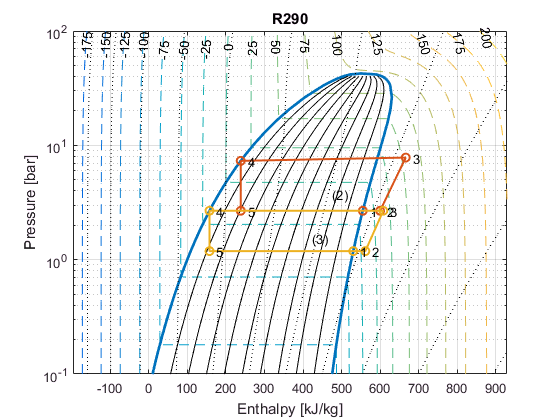

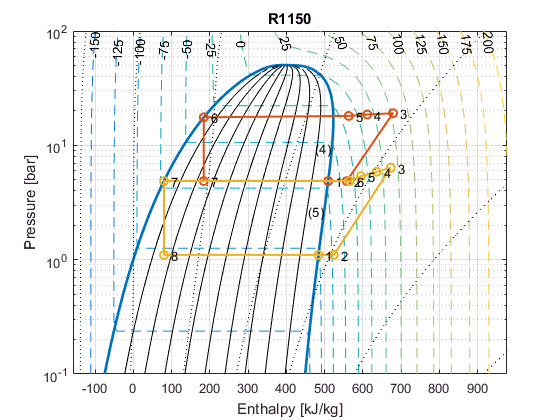

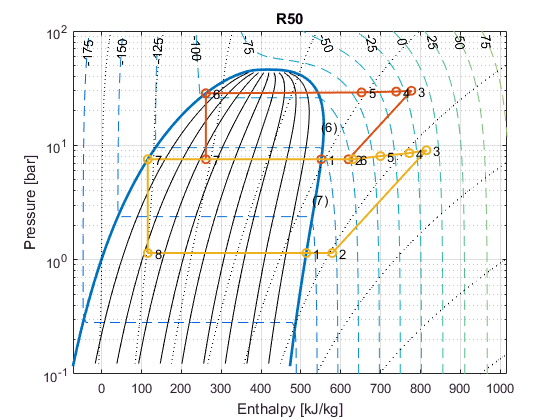

str1 = ExNr: 2,   R290, -17.4, [

str2 =  1 

ExNr: 2,   R290, -17.4, [ 1 ]\n

str1 = ExNr: 3,   R290, -38.4, [

str2 =  2 

ExNr: 3,   R290, -38.4, [ 2 ]\n

str1 = ExNr: 4,  R1150, -71.5, [

str2 =  3  2  1 

ExNr: 4,  R1150, -71.5, [ 3  2  1 ]\n

str1 = ExNr: 5,  R1150,  -102, [

str2 =  4  3  2  1 

ExNr: 5,  R1150,  -102, [ 4  3  2  1 ]\n

str1 = ExNr: 6,    R50,  -130, [

str2 =  5  4  3 

ExNr: 6,    R50,  -130, [ 5  4  3 ]\n

str1 = ExNr: 7,    R50,  -160, [

str2 =  6  5  4  3 

ExNr: 7,    R50,  -160, [ 6  5  4  3 ]\n

figures = struct;
for i = 1:length(Refrigerants)
    figures.(Refrigerants{i}) = figure;
    PlotPH(Mix(Refrigerants{i}),'pwindow',[1e4,1e7]), hold on
end

for i = 1:length(Cooler.Circuits)
    figure(figures.(Cooler.Circuits{i}.Refrigerant.Name));
    PlotProcess(Cooler.Circuits{i}.States,'ProcessName',Cooler.Circuits{i}.MyHeatExchangerNr)
    str1 = sprintf('ExNr: %d, %6s, %5.3g, [',...
        Cooler.Circuits{i}.MyHeatExchangerNr,...
        Cooler.Circuits{i}.Refrigerant.Name,...
        Cooler.Circuits{i}.Temperature);
    str2 = sprintf(' %d ',Cooler.Circuits{i}.UsedHeatExchangers);
    str3 = ']';
    fprintf('%s%s%s\n',str1,str2,str3)
end

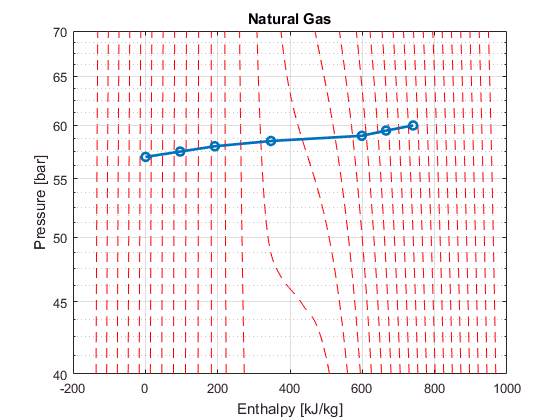


figures.(NG.Name) = figure;

if alternative == 3
    PlotNG
elseif alternative == 2
    PlotPH(NG,'pwindow',[50e5 70e5])
else
    disp('No Plot')
end
hold on

P = [];
H = [];
for i = 1:length(Gas.States)
    P(i) = Gas.States{i}.P;
    H(i) = Gas.States{i}.H;
end
plot(H/1e3,P/1e5,'-o','LineWidth',2), hold off